clear all;
channel_names = readtable('Channels.dat');
channel_names=table2cell(channel_names(:,2));

part_num=1;
intensitys=0.1:0.1:1;

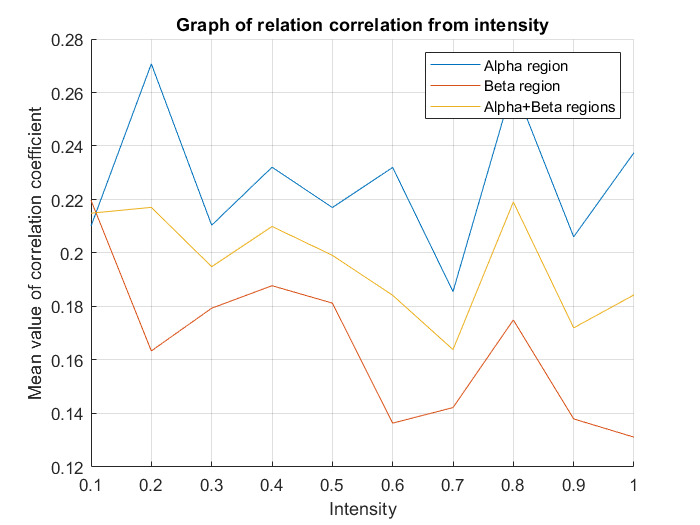

means_corr_alpha=zeros(size(intensitys));
means_corr_beta=zeros(size(intensitys));

for i=1:length(intensitys)
    intensity=intensitys(i);
    [data_alpha,data_beta]=Get_data_by_intencity(part_num,intensity,channel_names);
    [corr_alpha,mean_alpha]=Compute_corr(data_alpha,channel_names,0);
    [corr_beta,mean_beta]=Compute_corr(data_beta,channel_names,0);
%     disp([intensity,mean_alpha,mean_beta])
    
    means_corr_alpha(i)=mean_alpha;
    means_corr_beta(i)=mean_beta;
end

Visualization_intensity("Graph of relation correlation from intensity", "Mean value of correlation coefficient", means_corr_alpha, means_corr_beta, intensitys)

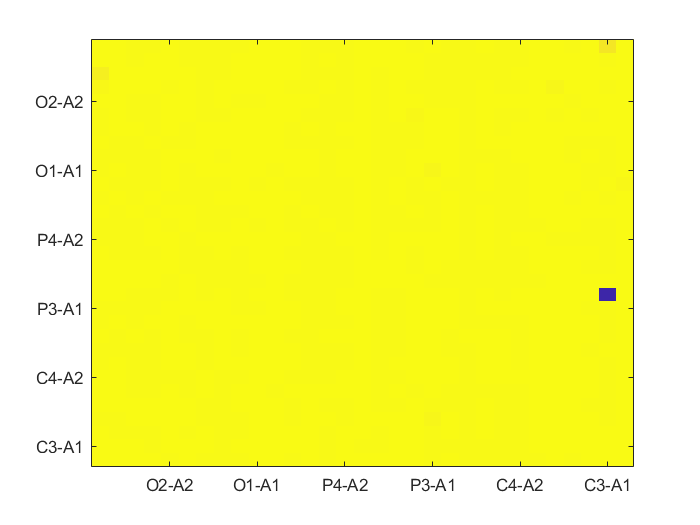

means_ANN_alpha = zeros(size(intensitys));
means_ANN_beta = zeros(size(intensitys));

for i = 7:length(intensitys)-1
    intensity=intensitys(i);
    [data_alpha,data_beta]=Get_data_by_intencity(part_num,intensity,channel_names);
    [perf_matr_alpha,mean_perf_alpha]=Compute_ANN_perf(data_alpha,channel_names,1);
    [perf_matr_beta,mean_perf_beta]=Compute_ANN_perf(data_beta,channel_names,0);
    disp([intensity,mean_perf_alpha,mean_perf_beta])

    means_ANN_alpha(i) = mean_perf_alpha;
    means_ANN_beta(i) = mean_perf_beta;
end


% Visualization_intensity("Graph of relation MSE trained in ANN from intensity", "Mean value of MSE coefficient in ANN", means_ANN_alpha, means_ANN_beta, intensitys)

function [] = Visualization_intensity(title_name, label, means_alpha, means_beta, intensitys)
figure()
hold on
plot(intensitys,means_alpha)
plot(intensitys,means_beta)
plot(intensitys,(means_alpha+means_beta)/2)
legend(["Alpha region", "Beta region","Alpha+Beta regions"])
xlabel("Intensity")
ylabel(label)
title(title_name)
grid on
end

function [perf_matr,mean_perf]=Compute_ANN_perf(data,channel_names,vis)
offset=min(data);
scale=ones(size(offset))./(max(data)-min(data));

data_NN=(data-offset).*scale;
perf_matr=zeros(length(channel_names));
for i=1:length(channel_names)
    for j=1:length(channel_names)
        x=data_NN(:,i);
        y=data_NN(:,j);
        [perf]=ANN_perfomance(x,y);
        perf_matr(i,j)=perf;
    end
end

mean_perf=mean(perf_matr,'all');

if vis==1
    Visualization_matrix(perf_matr,channel_names)
end
end

function [perf]=ANN_perfomance(x,y)
cv = cvpartition(size(x,1),'HoldOut',0.3);
idx = cv.test;
x_train=x(~idx,:);
y_train=y(~idx,:);
x_test=x(idx,:);
y_test=y(idx,:);
net=feedforwardnet(5);
net=train(net,x_train',y_train');
y_calc=net(x_test');
perf=1-mse(net,y_test',y_calc);
end

function [corr_,mean_]=Compute_corr(data,channel_names,vis)
corr_=corr(data,"type","Pearson");
mean_=(sum(corr_,'all')-length(channel_names))/(length(channel_names)^2-length(channel_names));

if vis==1
    Visualization_matrix(corr_,channel_names)
end
end

function []=Visualization_matrix(matrix,channel_names)
figure()
imagesc(matrix)
xticklabels(channel_names)
yticklabels(channel_names)
end

function [alpha_data,beta_data]=Get_data_by_intencity(part_num,intensity,channel_names)
part_folder="Participant "+num2str(part_num);
figs_for_spectra=part_folder+"\Figs for spectra\Backgr_int_"+num2str(intensity)+".dat";

channel_res=readtable(figs_for_spectra);
channel_res=table2array(channel_res(:,1:length(channel_names)));
channel_res=channel_res-mean(channel_res);

alpha_data=[];
beta_data=[];

for i=1:length(channel_names)
    [alpha_region,beta_region]=Frequency_regions_estimation(channel_res(:,i),0);
    alpha_data=[alpha_data,alpha_region];
    beta_data=[beta_data,beta_region];
end
end

function [alpha_region,beta_region]=Frequency_regions_estimation(X, vis)
alpha=[8,12];
beta=[15,30];
Fs=250;                   
L=length(X);

n=2^nextpow2(L);

Y=fft(X,n);
f=Fs*(0:(n/2))/n;
P=abs(Y/n);

alpha_limits=(f>=alpha(1)).*(f<=alpha(2));
alpha_freq=nonzeros(f.*alpha_limits);
alpha_region=nonzeros(P(1:n/2+1)'.*alpha_limits);

beta_limits=(f>=beta(1)).*(f<=beta(2));
beta_freq=nonzeros(f.*beta_limits);
beta_region=nonzeros(P(1:n/2+1)'.*beta_limits);

if vis==1
    figure()
    hold on
    plot(alpha_freq,alpha_region)
    plot(beta_freq,beta_region)
    % plot(f,P(1:n/2+1)) 
    xlabel('Frequency (f)')
    ylabel('|P(f)|')
end

end